# Odometry

Odometers are sensors that measure the wheels revolution .  **Odometry** is the use of data from  odometers to estimate change in position over time. In practice, odometers works by rotary encoders that measure the spin of each wheel. In a differentian robot  kwnowing the wheels radio, distance from the center robot to heach wheel and information from Odometer is easy to compute robot pose.

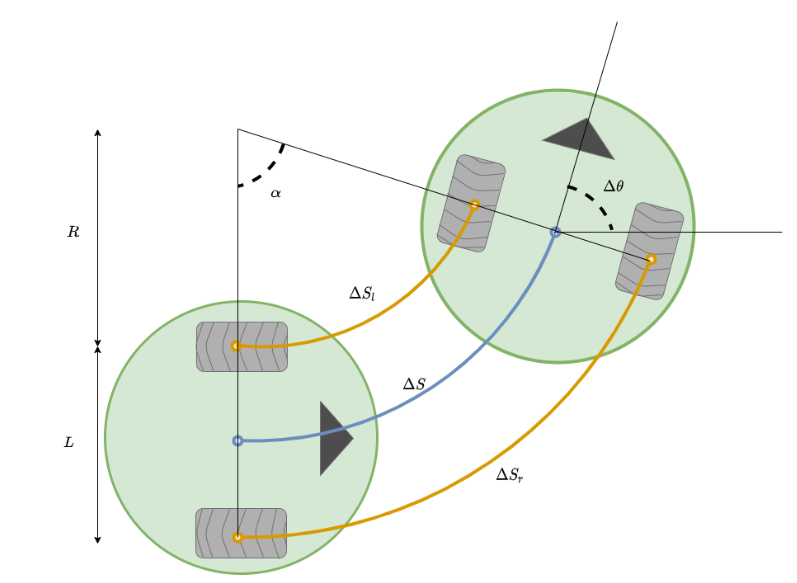

$\Delta S_l =R\alpha$;   ---(1)                

$\Delta S_r =\left(R+L\right)\alpha ;$  ---(2)   

$\Delta S=\left(R+\frac{1}{2}L\right)\alpha ;$  ---(3)

As you can see in the image above, the trajectory in each wheel $\Delta S_l$ and ${\Delta S}_r$ generate a trajectory that moves the robot  $\Delta S$ it can be calculated as shown below:

From  equation (2):  $R=\frac{\Delta S_r }{\alpha }-L$ substitute  in (1) equation: $\Delta S_l =\left(\frac{\Delta S_r }{\alpha }-L\right)\alpha =\Delta S_r -L\alpha$     then   $L\alpha =\Delta S_r -\Delta S_l$  substitute last result in $\Delta S$:   $\Delta S=R\alpha +\frac{1}{2}\left(\Delta S_r -\Delta S_l \right)\;$   remember that  $\Delta S_l =R\alpha$  so:  $\Delta S=\Delta S_l +\frac{1}{2}\left(\Delta S_r -\Delta S_l \right)$    **finally**:  $\Delta S=\frac{\Delta S_l +\Delta S_r }{2}$

##  ¿How can we calculate the new robot angle? 

So we solve for α by equating α from (1) and (2) equations:


$$\frac{\Delta S_l }{R}=\frac{\Delta S_r }{R+L}$$



$$\left(R+L\right)\;\Delta S_l =R\;\Delta S_r$$



$$L\;\Delta S_l =R\;\left(\Delta S_r -\Delta S_l \right)$$



$$R=\frac{L\;\Delta S_l }{\Delta S_r -\Delta S_l }$$


Substitute $R$ into $\alpha =\frac{\Delta S_l }{R}$:  $\alpha =\frac{{\Delta S}_l \left(\Delta S_r -\Delta S_r \right)}{L\;\Delta S_l }=\frac{\left(\Delta S_r -\Delta S_r \right)}{L\;}$  

Observe in the image that $\Delta \theta$ equals the rotation about the circular arc´s center ($\alpha$) point so:

    
$$\Delta \theta =$$

$$\frac{\left(\Delta S_r -\Delta S_l \right)}{L\;}$$


## Global coordinates

Because we already now how to calculate  $\Delta s$ and $\Delta \theta$ It's possible to calculate the robot pose in global coordinates.

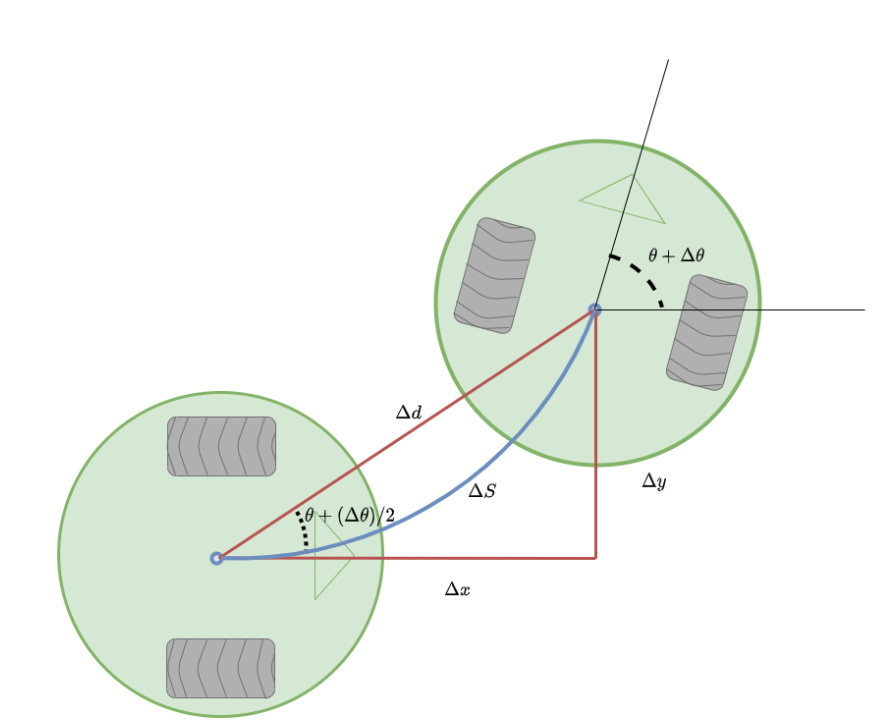


$$\Delta x=\Delta d\;\cos \left(\theta +\frac{\Delta \theta }{2}\right)$$



$$\Delta y=\Delta d\;\sin \left(\theta +\frac{\Delta \theta }{2}\right)$$


If we assume that the motion is short $\Delta d\approx \Delta S\;\textrm{so}:$


$$\Delta x=\Delta S\;\cos \left(\theta +\frac{\Delta \theta }{2}\right)$$



$$\Delta y=\Delta S\;\sin \left(\theta +\frac{\Delta \theta }{2}\right)$$


Finaly the odometry can be calculate by:

 
$$\Delta x=\Delta S\;\cos \left(\theta +\frac{\Delta \theta }{2}\right)$$



$$\Delta y=\Delta S\;\sin \left(\theta +\frac{\Delta \theta }{2}\right)$$



$$\Delta S=\frac{\Delta S_l +\Delta S_r }{2}$$



$$\Delta \theta =$$

$$\frac{\left(\Delta S_r -\Delta S_l \right)}{L\;}$$


The actual pose is a function that depence on previos pose:


$$\overrightarrow{x_t } ={\overrightarrow{x} }_{t-1} +\left\lbrack \begin{array}{c}
\frac{\Delta S_l +\Delta S_r }{2}\cos \left(\theta +\frac{\Delta S_r -\Delta S_l }{2L}\right)\\
\frac{\Delta S_l +\Delta S_r }{2}\sin \left(\theta +\frac{\Delta S_r -\Delta S_l }{2L}\right)\\
\frac{\left(\Delta S_r -\Delta S_l \right)}{L\;}
\end{array}\right\rbrack$$
 

## Odometry in simulation

Define a visualizer and set up  a diferential robot (as you learned in previous lessons).

viz = Visualizer2D;
initPose = [ 0; 0; 0]; % [x ; y ; theta]    

R = 0.1; 
L = 0.5; 
mobileRobot = DifferentialDrive(R,L);
viz.robotRadius = .3;


wL = pi/2; % [rad/s]
wR = pi; % [rad/s]

[v,w] = forwardKinematics(mobileRobot,wL,wR);

bodyV = [v;0;w];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in y axis.


Define an array of poses where  we  will store each pose computed by odometry.

odom_pose = zeros(3,numel(tVec));
odom_pose(:,1) = initPose;
currentPose = initPose;

[sampleTime,tVec,r] = simulTime(0.1,10); % Define Sample time, time array and rate control 
for idx = 2:numel(tVec) 


  Compute  odometry as describe at the top of this script.

    d_sr = R * wR * sampleTime;
    d_sl = R * wL * sampleTime;
    d_s = (d_sr + d_sl)/2;
    d_theta = (d_sr - d_sl)/L;
    
    % Store each pose computed by odometry
    odom_pose(:,idx) = odom_pose(:,idx-1) + [ d_s *cos(odom_pose(3,idx-1) +  d_theta/2 ) ; 
                                              d_s *sin(odom_pose(3,idx-1) +  d_theta/2 );
                                              d_theta];             
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
      
    % Update visualization
    viz(currentPose);

    %Wait for visualization rate
    waitfor(r);
end


Finally  plot odometry information in the same visualizer.

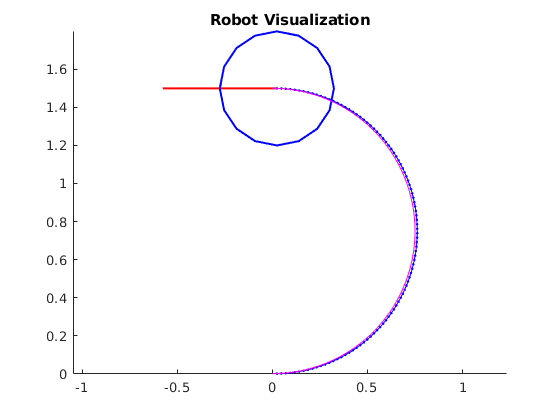

hold on
plot(odom_pose(1,:),odom_pose(2,:),'m');

# Practice

### What happend if the sampleTime decrease (for example 1  second) ?

### Try it yourself and explain the result.